# Thuật toán ABC (artificial bee colony)

## Giới thiệu

Trong mô hình ABC, đàn ong nhân tạo bao gồm ba nhóm ong: **ong thợ, ong quan sát **và** ong trinh sát**. Giả thiết rằng, một con ong thợ có thông tin cho một nguồn thức ăn. Nói cách khác, số lượng ong thợ trong đàn bằng số lượng nguồn thức ăn xung quanh tổ. Những con ong thợ sẽ đi tìm nguồn thức ăn và trở về tổ và "**nhảy**" để thông tin về khu vực này. Con ong thợ có nguồn thức ăn bị bỏ rơi (ong quan sát không quan tâm đến nó) sẽ trở thành ong trinh sát và bắt đầu tìm kiếm nguồn thức ăn mới. Ong quan sát theo dõi các điệu "**nhảy**" của những con ong thợ và chọn nguồn thức ăn tùy theo điệu "**nhảy**".

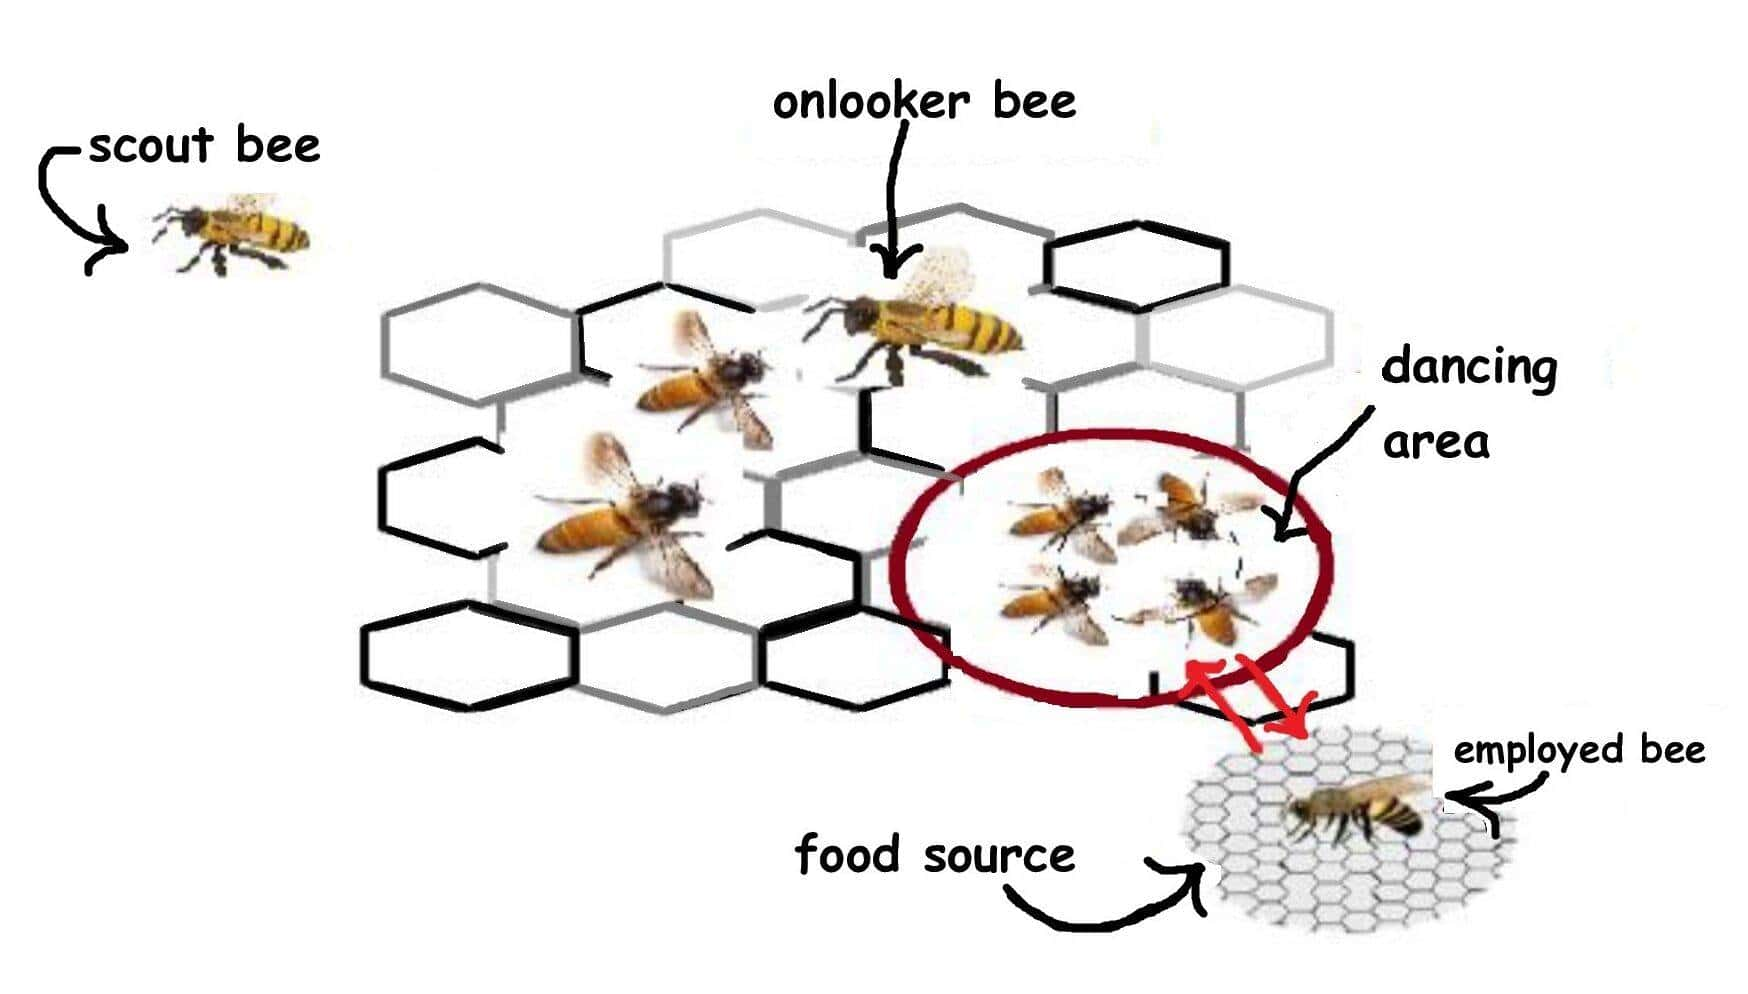

**Các bước chính của thuật toán được đưa ra dưới đây:**

    1. Nguồn thức ăn ban đầu được khởi tạo cho tất cả những con ong thợ

**LOOP** 

    2. Mỗi con ong thợ sẽ đi đến một nguồn thức ăn trong trí nhớ của mình và xác định nguồn thức ăn gần nhất, sau đó đánh     giá lượng mật hoa của nó và "nhảy" múa trong tổ. 

    3. Mỗi con ong quan sát  theo dõi điệu nhảy của những con ong thợ và chọn một trong những nguồn của chúng tùy thuộc vào điệu nhảy, sau đó đi đến nguồn đó. Sau khi chọn một lân cận xung quanh đó, nó đánh giá lượng mật hoa của nguồn thức ăn đó.

    4. Những nguồn thức ăn được xác định là bỏ đi sẽ được thay thế bằng những nguồn thức ăn mới do ong trinh sát phát hiện.

    5. Nguồn thức ăn tốt nhất được tìm thấy sẽ được ghi nhớ lại. 

**UNTIL** (điều kiện dừng được đáp ứng)

           Trong ABC (thuật toán dựa trên quần thể), vị trí của nguồn thức ăn thể hiện một lời giải tạm thời cho vấn đề tối ưu hóa và lượng mật hoa của nguồn thức ăn tương ứng với chất lượng (phù hợp) của lời giải. Số lượng ong thợ bằng với số lượng lời giải  trong quần thể. Ở bước đầu tiên, một quần thể ban đầu được phân bố ngẫu nhiên (các vị trí nguồn thức ăn) được tạo ra. Sau khi khởi tạo, quần thể phải lặp lại các chu kỳ trong quá trình tìm kiếm của những con ong thợ, những con ong quan sát và những con ong trinh sát tương ứng. Một con ong thợ tạo ra một sự thay đổi về vị trí nguồn thức ăn trong trí nhớ của nó và phát hiện ra vị trí nguồn thức ăn mới. Với điều kiện lượng mật của nguồn mới cao hơn nguồn trước đó, con ong sẽ ghi nhớ vị trí nguồn mới và quên mất nguồn cũ. Nếu không thì nó ấy sẽ giữ vị trí của người đó trong trí nhớ của mình. Sau khi tất cả những con ong thợ hoàn tất quá trình tìm kiếm, chúng chia sẻ thông tin vị trí của các nguồn với ong quan sát tại tổ. Mỗi con ong quan sát đánh giá thông tin mật hoa lấy từ tất cả những con ong thợ và sau đó chọn nguồn thức ăn tùy thuộc vào lượng mật hoa của nguồn. Giống như trường hợp của con ong thợ, nó tạo ra một sự thay đổi về vị trí nguồn mật trong trí nhớ của mình và kiểm tra lượng mật hoa của nó. Với điều kiện mật hoa của nó cao hơn vị trí trước đó, con ong sẽ ghi nhớ vị trí mới và quên vị trí cũ. Các nguồn được xác định là bỏ thì sẽ có các nguồn mới được tạo ngẫu nhiên để thay thế bởi các trinh sát nhân tạo.

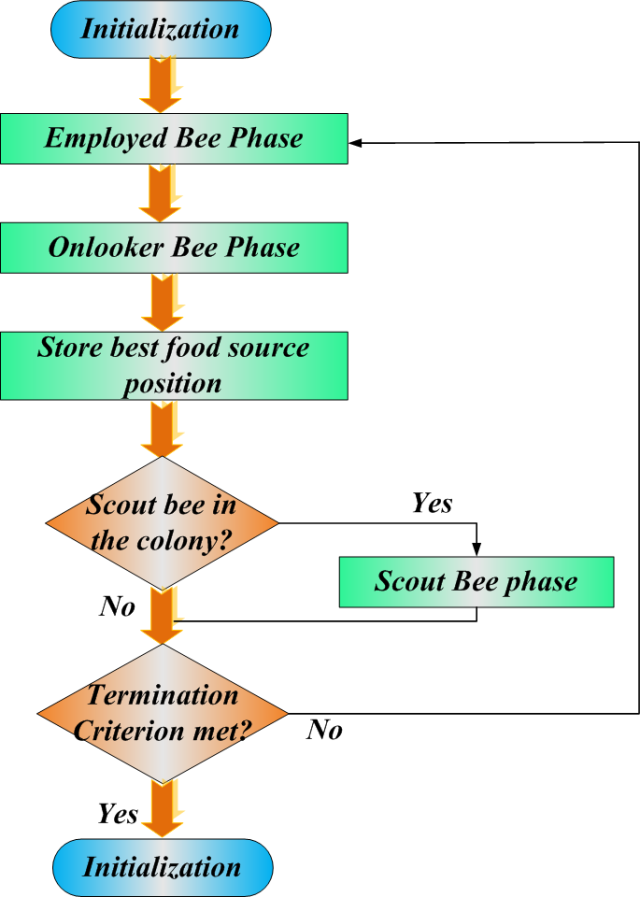

Sơ đồ thuật toán

Ví dụ bài toán tối ưu hàm f(x,y) =  (x-2)^2  + (y-3)^2; Tìm cực tiểu của hàm f(x,y) trên miền -10 <= x <= 20; 10<= y <= 10.

## Task 1. Khai báo hàm fitness()

Your code here Task 1

Hàm fitness return result of F(x,y). The less fitness, the more optimize position of food source. 

## Task 2. Khởi tạo bầy ong nhân tạo và các thông số bài toán 

 
clc;clear;
% Các thông số bầy ong nhân tạo
numBees = 50; % Số lượng ong
maxIterations = 1000; % Số lượng vòng lặp tối đa
numEmployedBees = round(0.5 * numBees); % Số lượng ong thợ (bằng 1/2 số lượng ong trong bầy)
numOnlookerBees = numBees - numEmployedBees; % Số lượng ong quan sát

% Các thông số bài toán
numDimensions = 2; % Số chiều của không gian tìm kiếm
lb = [-10, -10]; % Giới hạn dưới của không gian tìm kiếm
ub = [20, 10]; % Giới hạn trên của không gian tìm kiếm

## Task 3. Khởi tạo các mảng chứa tọa độ và nghiệm tạm thời

 
% Khởi tạo các mảng chứa thông số tọa độ của bầy ong
employedBees = zeros(numEmployedBees, numDimensions); % Mảng chứa vị trí ong thợ
onlookerBees = zeros(numOnlookerBees, numDimensions); % Mảng chứa vị trí ong quan sát
fitness = zeros(numBees, 1); % Mảng chứa giá trị fitness của từng ong (cả ong thợ và ong quan sát)
trial = zeros(numBees, 1); % Mảng chứa số lần thử của từng ong trong đàn(số lần onlooker bee skips employed bee).

% Khởi tạo giá trị tốt nhất và nghiệm tốt nhất

bestSolution = [0 0]; % Giải pháp tốt nhất
bestFitness = inf; % Giá trị fitness tốt nhất

## Task 4. Khởi tạo nguồn thức ăn của Ong thợ

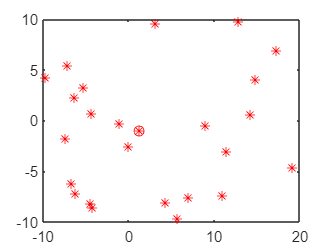

 
% -------------------------- task 4 ----------------------------------------
% --------------------------- Code here ------------------------------------
% Khởi tạo nguồn thức ăn của từng Ong thợ
for i = 1:numEmployedBees
    employedBees(i, :) = lb + rand(1, numDimensions) .* (ub - lb);

    % Tính giá trị fitness cho từng nguồn thức ăn của ong thợ

    fitness(i) =  objectiveFunction(employedBees(i,1), employedBees(i,2));


    % -------------------------  task 5  ---------------------------------------
    % -------------------------  Code here--------------------------------------
    % Find the best solution and fitness value using bubule algorithm. 
    if fitness(i)< bestFitness
        bestSolution= employedBees(i, :);
        bestFitness= fitness(i);
    end


    % ------------------------- kết thúc task 5  -------------------------------


end

% plot(employedBees(:,1),employedBees(:,2),'r*')
plot(employedBees(:,1),employedBees(:,2),'r*');
hold on
plot(bestSolution(1,1), bestSolution(1,2), 'ro');
hold off

fprintf('Current best solution: %f, %f', bestSolution(1,1), bestSolution(1,2));

Current best solution: 1.241378, -0.938625

fprintf('Expected solution: 2,3');

Expected solution: 2,3

% ---------------------- kết thúc task 4 -----------------------------------

## Task 5. Khởi tạo nguồn thức ăn của ong thợ

Thực hiện kiểm tra nếu nguồn thức ăn của ong thợ (fitness) là tốt hơn của **bestSolution** gán giá trị nguồn thức ăn đó cho **bestSolution** và  **bestFitness**.  (Above).

## Task 6. Thực hiện vòng lặp chính

% Bee Colony Optimization Main Loop
for iter = 1:maxIterations
    % Đối với ong thợ. Force employee bees to move around its position. 
    for i = 1:numEmployedBees
        v = employedBees(i, :); % Vị trí ong thợ hiện tại
        j = randi([1, numDimensions]); % Chọn ngẫu nhiên một chiều để tối ưu hóa
        %( Nếu 1 chiều đã tối ưu rồi thì quá trình hội tụ sẽ nhanh hơn). 
        % Tìm vị trí mới cho ong thợ
        k = randi([1, numEmployedBees]);
        while k == i
            k = randi([1, numEmployedBees]);
        end

        v(j) = employedBees(i, j) + rand() * (employedBees(i, j) - employedBees(k, j));
        
        % Kiểm tra vị trí mới của ong thợ có nằm trong giới hạn của không gian tìm kiếm
        % Clamp it in bound
        v = max(v, lb);
        v= min(v, ub);

        % Tính giá trị fitness cho vị trí mới
        newFitness = objectiveFunction(v(1,1), v(1,2));
        
        % So sánh giá trị fitness mới với giá trị fitness hiện tại
        if newFitness < fitness(i)
            employedBees(i, :) = v;
            fitness(i) = newFitness;

            % Cập nhật giải pháp tốt nhất nếu cần
            if newFitness < bestFitness
                bestSolution = v;
                bestFitness = newFitness;
            end
        else
            % Kiểm tra số lần nguồn thức ăn của ong thợ có đủ tốt không?
            trial(i) = trial(i) + 1;  

        end
    end
end


## Task 7. Phương pháp chọn ong thợ 

Phương pháp chọn ong thợ dựa trên vòng quay roulette. Để chắc chắn luôn luôn có 1 con ong được lựa chọn giá trị r = rand() được tạo ra sau đó so sánh với giá trị 

c = cumsum(probabilities);

Hoàn thiện code cho task 8

## Task 8. Thực hiện thuật toán với ong quan sát

Mỗi ong quan sát sẽ lựa chọn bất kỳ 1 ong thợ để bay đến lân cận của nó( theo 1 chiều bất kỳ), nếu như nó bay đến và tìm thấy vị trí có fitness nhỏ hơn thì update bestFitness/solution và chỉ thị ong thợ bay đến đó để lưu nguồn thức ăn mới, không thì tăng giá trị trial ( Ong quan sát không lưu nguồn thức ăn)

Khi trial >10, biến ong thợ thành ong trinh sát bằng cách khởi tạo lại vị trí nguồn thức ăn của nó và reset trial. 

% Đối với ong quan sát
for i = 1:numOnlookerBees
    % Tính xác suất chọn ong thợ. Lưu vào mảng probabilities
    probabilities = fitness ./ sum(fitness); 
    % Chọn một ong thợ dựa trên xác suất
    selectedBee = rouletteWheelSelection(probabilities);

    v = employedBees(selectedBee, :); % Vị trí ong thợ được chọn
    j = randi([1, numDimensions]); % Chọn ngẫu nhiên một chiều để tối ưu hóa

    % Tìm vị trí mới cho ong thám hiểm dựa trên ong thợ
    k = randi([1, numEmployedBees]);
    while k == selectedBee
        k = randi([1, numEmployedBees]);
    end
    v(j) = employedBees(selectedBee, j) + rand() * (employedBees(selectedBee, j) - employedBees(k, j));

    % Kiểm tra giới hạn của không gian tìm kiếm
    v= max(v, lb);
    v= min(v, ub);
    
    % Tính giá trị fitness cho vị trí mới
    newFitness = objectiveFunction(v(1,1), v(1,2));

    % So sánh giá trị fitness mới với giá trị fitness hiện tại
    if newFitness < fitness(selectedBee)
        employedBees(selectedBee, :) = v;
        fitness(selectedBee) = newFitness;

        % Cập nhật giải pháp tốt nhất nếu cần
        if newFitness < bestFitness
            bestSolution = v;
            bestFitness = newFitness;
        end
    else
        trial(selectedBee) = trial(selectedBee) + 1;
    end
end

% Scout Bees Phase - Biến ong thợ thành -> Ong trinh sát
maxTrials = max(trial);
if maxTrials >= 10
    index = find(trial == maxTrials, 1);
     % Khởi tạo lại vị trí ong thợ
    employedBees(index, :)= lb+  rand(1, numDimensions).*(ub-lb);
     % Tính giá trị fitness mới
    fitness(index) = objectiveFunction(employedBees(index,1), employedBees(index, 2));
    trial(index) = 0;
end
% Display Best Fitness at Each Iteration
disp(['Iteration ', num2str(iter), ', Best Fitness = ', num2str(bestFitness)]);

Iteration 1000, Best Fitness = 3.1648e-18



% Hiển thị giải pháp tốt nhất
disp('Best Solution:');

Best Solution:


disp(bestSolution);

    2.0000    3.0000



disp('Best Fitness:');

Best Fitness:


disp(bestFitness);

   3.1648e-18



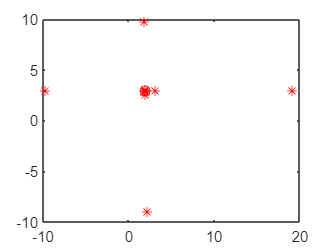

plot(employedBees(:,1),employedBees(:,2),'r*');
hold on
plot(bestSolution(1,1), bestSolution(1,2), 'ro');

function fitness = objectiveFunction(x,y) % Hàm mục tiêu (ví dụ)
% ---------------------------------- Task 1 --------------------------------
% ------------------------------------- your code here ---------------------
fitness = (x-2)^2  + (y-3)^2;
end

% Phương pháp chọn ong thợ dựa trên vòng quay roulette (roulette wheel
% selection)
function selectedBee = rouletteWheelSelection(probabilities)
r = rand();
c = cumsum(probabilities);   % Giá trị cuối của c là 1 (tổng xác suất) để đảm bảo luôn chọn được 1 ong thợ

% ------------------------------------- your code here --------------------------------------
selectedBee= find(r<=c, 1);
end